# Stochastic Resonance

22Nov24 BR

Noise is not always bad. Here we generate a time series and simulate digitizing it, i.e., measuring the signal with an analog-to-digital converter (ADC). Due to limited resolution of the digitization process, the signal is distorted. However, by adding noise to the signal *before* digitizing, the degradation is actually reduced. This is a demonstration of a phenomena called stochastic resonance [1]. It has been shown to be the underlying process behind accute sensitivity in a number of biological systems. Note that the signal is generally less than 1 bit, and would thus seem to be unrecoverable, however it is nearly fully recovered by the addition of noise! 

We'll use a simulated bandpass filter routine that I wrote, `bpfft.m`, in the Appendix, to simulate a wiggly random time series. Rounding the time series simulates an ideal ADC. Filtering the ADC output to the known bandwidth of the input signal is the best we can do to reconstruct the original waveform (without adding noise).

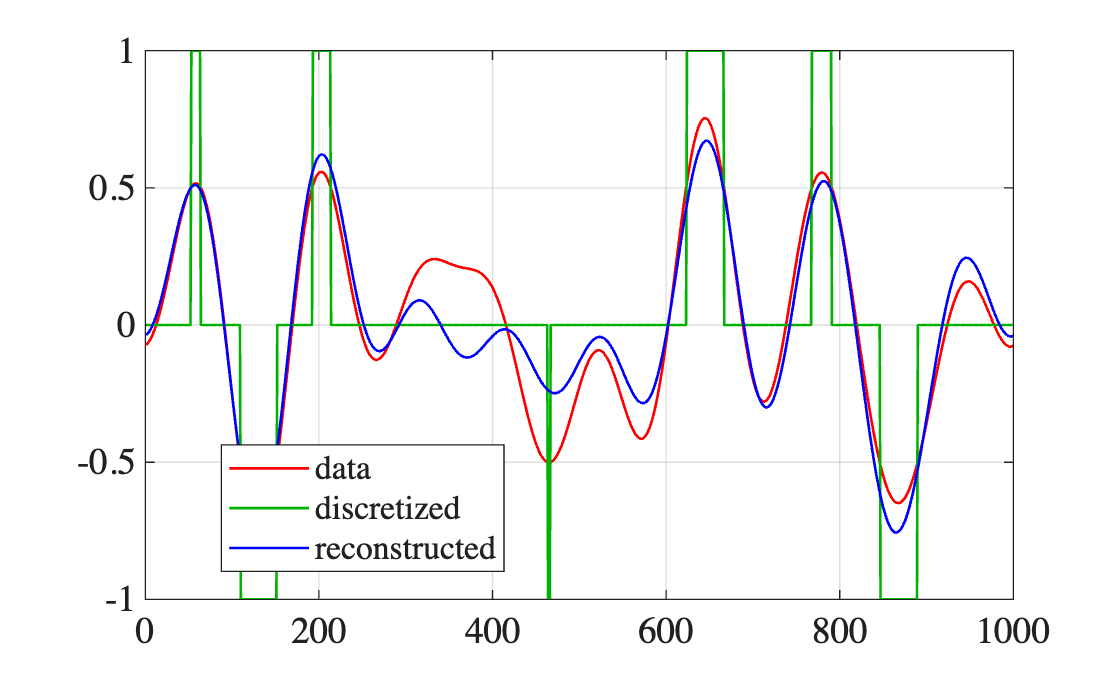

a = bpfft(rand(1000, 1), 1000, 1, 10) * 10; 	% generate a low-pass filtered time series
ra = round(a); 	% discretize the time series
fra = bpfft(ra, 1000, 1, 10); 	% filter the discretized data
plot([a ra fra]); legend('data', 'discretized', 'reconstructed','location','best');
grid

err = rms(a - fra), 	% rms error

err = 0.1106

Now let's add some Gaussian random noise to the same signal followed by the same signal processing. You can see we added quite a lot of noise -- I encourage you to play with the noise amplitude -- too much and too little are no good, but there is a Goldilocks amount that minimizes the error -- hence the term "resonance".

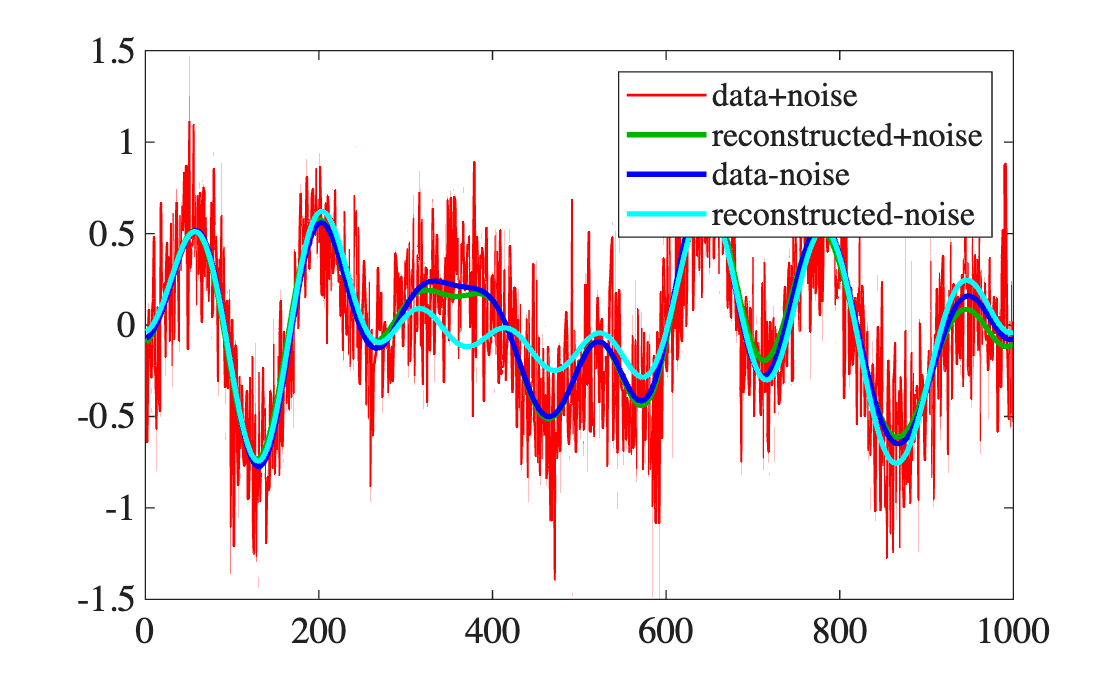

b = a + randn(size(a)) * .3; 	% add some gaussian noise to data
rb = round(b); 	% discretize
frb = bpfft(rb, 1000, 1, 10); 	% filter
h = plot([b frb a fra]); 
legend('data+noise','reconstructed+noise', 'data-noise', 'reconstructed-noise');
set(h(2:end),'linewidth',2);

err2 = rms(a - frb); 	% error with stochastic resonance
fprintf('rms err w/o noise = %.3f\nrms error w/noise = %.3f\nrms error reduced by %.1f percent\n', ...
    err, err2, err/err2*100)

rms err w/o noise = 0.111
rms error w/noise = 0.040
rms error reduced by 276.7 percent


Adding noise reduced the rms reconstruction error substantially -- so when is noise "good"? 

What makes this work is the nonlinearity in the discrete sampling process -- `round(x)` is nonlinear. The error is especially reduced where the data was close to +-.5, so the noise threw it over the threshold. Neurons are also strongly nonlinear -- an action potential [2] is a binary all-or-none event, so noise added to a stimulus before the action potential can improve detection thresholds, and biology figured this out and uses it (e.g., in your auditory system) [3]. 

## Why it is called "resonance"

Let's repeat this reconstruction with a longer data set and plot rms error vs. noise amplitude

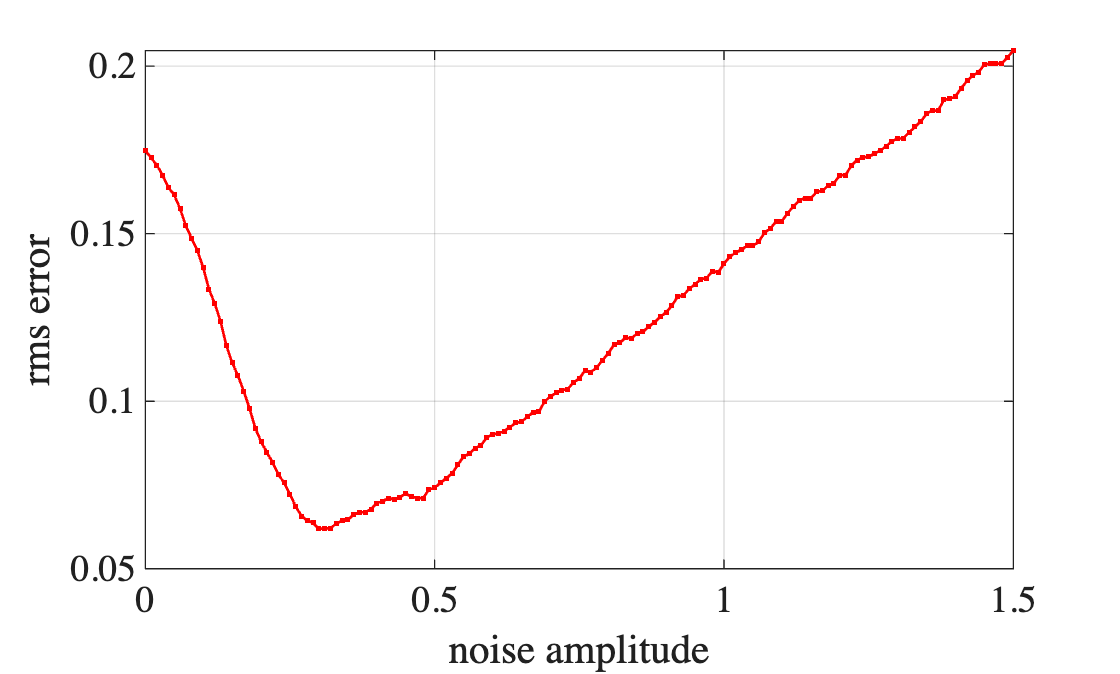

a = bpfft(rand(10000, 1), 1000, 1, 10) * 10;
noise = randn(size(a));
noiseAmpl = 0:.01:1.5;
rmsErr = zeros(size(noiseAmpl));
noise = randn(size(a));
for i=1:length(noiseAmpl)
    b = a + noiseAmpl(i) * noise; 	% add some gaussian noise to data
    rb = round(b); 	% discretize
    frb = bpfft(rb, 1000, 1, 10); 	% filter
    rmsErr(i) = rms(a - frb);
end
plot(noiseAmpl, rmsErr, '.-'); grid
xlabel('noise amplitude'); ylabel('rms error')

Adding the right amount of noise (~1/3 of the unit (nonlinear) discretion step in this case) reduces error in data reconstruction by about ~3 times. Not exactly a simple resonance curve, but this has the characteristic of one -- that less or more noise amplitude results in worse reconstruction -- there is an optimal parameter like a resonant frequency, $\omega_0$. 

## Another example in 2-d -- Superresolution image processing

Imagine you have an image processing task of locating cars on the ground from a high altitude aerial view. Would that be possible if the cars image size was  << 1 pixel across? Biologists face a similar problem of localizing small structures or molecules molecules in tissue samples. Molecules are on the order of 1-10nm in size, and camera pixels are ~5um across, about 1000 linear times larger (a *million* times the area of a molecule). 

There's no way to "see" individual molecules with a light microscope -- the wave nature of light limits spatial resolution to around $\lambda/4 \approx 100$nm. So it wouldn't be possible to find cars in an image with pixels spanning 10 meters ... unless ... *what if* the image was taken at night and (only) the cars had their lights turned on? Two cars close enough that their light landed on the same pixel might be indistinguishable (in a single image), but the signal processing task suddenly becomes tractable with this change in signal/noise ratio. 

Back to biology, fluorescent molecules aren't generally common, so sparse molecules (if bright enough) could be localized to a pixel. But could you do much better localization, e.g., how did I accomplish 1/20 pixel localization, known as "superresolution"?

The simple answer is not stochastic resonance, but instead adding a systematic form of noise. I defocused the image onto the camera. When the image is in focus, all the signal from a point source usually lands on one pixel, and a pixel doesn't differentiate whether the signal is from its right, top, ... side. Unfocused, the light from the spot spreads over several pixels. Adding up the rows and columns of intensity results in two approximately Gaussian curves, who's peaks are approximately parabolic. Polyfit each peak --> $I(x)$ = p(1)x^2+p(2)x+p(3), which has a peak location at $\frac{dI}{dx} = 0$ or $x_{peak}$= -p(2)/(2*p(1)), and likewise for the intensity $I(y)$. I attempted this on real images, but was frustrated by our inability to grow cardiomyocytes [4].

## References

[1] [https://en.wikipedia.org/wiki/Stochastic_resonance](https://en.wikipedia.org/wiki/Stochastic_resonance) 

[2] [https://en.wikipedia.org/wiki/Action_potential](https://en.wikipedia.org/wiki/Action_potential) 

[3] [https://en.wikipedia.org/wiki/Stochastic_resonance_(sensory_neurobiology)](https://en.wikipedia.org/wiki/Stochastic_resonance_(sensory_neurobiology)) 

[4] Ramirez J, Eckert B, Gephart A, Delgado J, Chavez N, Hicks R, Rasnow B (2017) [Imaging Cardiomyocyte Beating Across Entire Microtiter Plates.](http://www.rasnowpeak.com/brian/pub/CMSagePoster04May17.pdf) 9th Annual SAGE Student Research Conference, CSUCI.

### Appendix: bpfft.m: 

function d = bpfft(v,rate,fo,f1)
% function d = bpfft(v,rate,fo,f1)
% bandpass fft rows of matrix v.  v is sampled at rate (Hz)
% The pass band is fo < f < f1.

% mod. 1-19-92, B.R. to take col vectors instead of rows.
% mod. 13 dec 94, B.R. fixed bug in indexing that messed up 
% values at the endpts slightly

n = length(v);
ffo = round(fo * n / rate);
if fo == 0,  ffo = -1; end
ff1 = round(f1 * n / rate);
fb = fft(v);
fb([1:ffo+1 ff1+1:n-ff1+1 n-ffo+1:n],:) = ...
     zeros(size(fb([1:ffo+1 ff1+1:n-ff1+1 n-ffo+1:n],:)));
d = real(ifft(fb));
end